# **Metody Optymalizacji**

## **Optymalizacja wielokryterialna**

**Roman Nowak, AGH, WEAIiIB, Automatyka i robotyka**

## **Wstęp**

    W poprzednich ćwiczeniach z laboratorium metod optymalizacji, zadaniem było wyznaczenie minium dla jednej funkcji celu $F(x)$ - jednego kryterium. Sprowadzało się to do obliczenia ekstremum tylko tej jednej funkcji. W rzeczywistości problemy optymalizacyjne, często wymagają uwzględnienia większej liczby kryteriów $F_i$ , które, często mogą być ze sobą sprzeczne. Takie zadanie nazywamy optymalizacją wielokryterialną. Sprowadza się ono do znalezienia minimum funkcji wektrowej $F(x) = \{F_1(x), F_2(x), ..., F_m(x)\}$. Otrzymujemy więc problem optymalizacji pewnego wektora funkcji celu (kryteriów), na który dodatkowo mogą być nałożone ograniczenia: 

- równościowe: $G_i(x) = 0$,

- nierównościowe: $G_i(x) \leq 0$,

- dotyczące zmiennych niezależnych: $x_l \leq x \leq x_u$, gdzie $x_l$ - dolne ograniczenie, $x$ - zmienna, $x_u$ - górne ograniczenie

W Matlabie w celu rozwiązania tego rodzaju problemów, możemy skorzystać z *Matlab Optimization Toolbox*, w szczególności z funkcji:

- `fminimax`

- `fgoalattain`

### **Zastosowanie funkcji fminimax**

    Funkcję `fminimax`, możemy zastosować w celu znalezienia punktu minimalizującego maksimum zbioru funkcji celu.

    Może ona przyjmować od 2 do 10 argumentów. Konieczne do zadziałania funkcji jest podanie tylko pierwszych dwóch:

- *fun *- wektor funkcji celu;

- *x0 *- wektor punktów początkowych

Kolejne parametry odpowiadają za ograniczenia dla funkcji celu. Są to kolejno: *A, b, Aeq, beq, lb, ub.*

I ograniczają wektor zmiennych $x$, w nastęujący sposób: $A\cdot x \leq b; Aeq\cdot x=beq; lb \leq x \leq ub$.

Następny parametr - *noncol*, odpowiada za równościowe, lub nierównościowe ograniczenia nieliniowe.

Ostatni parametr to *options, *który służy dostosowaniu opcji działania `fminimax`.

    Na wyjściu możemy otrzymać warości. Są to kolejno:

- *x* - znalezione minimum;

- *fval* - wartość funkcji celu w minimum x;

- *maxfval* - maksymalna wartość funkcji celu w rozwiązaniu x;

- *exitflag* - opisuje warunek wyjściowy `fminimax`;

- *output* - struktura z inforamcjami o precesie optymalizacji;

- *lambda* - struktura zawierająca mnożniki Lagrange'a.

   Działanie funkcji `fminimax` najlepiej pokazać na jednym z przykładów, zaczerpniętym z dokumentacji Matlaba.

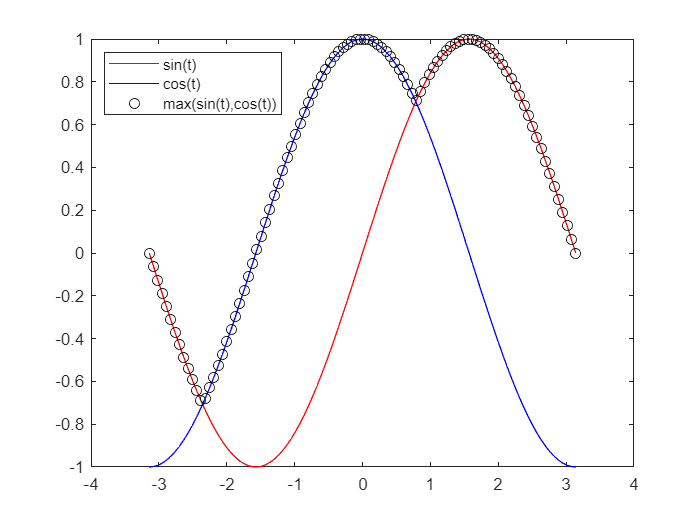

clear;
t = linspace(-pi,pi);
figure;
plot(t,sin(t),'r-');
hold on;
plot(t,cos(t),'b-');
plot(t,max(sin(t),cos(t)),'ko');
legend('sin(t)','cos(t)','max(sin(t),cos(t))','Location','NorthWest');
hold off;

Funkcja `fminimax`, znajdzie minimum dla funkcji, której przebieg jest zaznaczony czarnymi kołami. To, które z dwóch widocznych minimum odnajdziemy, zależne jest od watości początkowej x0. Poniżej działanie dla x0 = 1.

fun = @(x)[sin(x);cos(x)];
x0 = 1;
x1 = fminimax(fun,x0)


Local minimum possible. Constraints satisfied.

fminimax stopped because the size of the current search direction is less than
twice the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x1 = 0.7854

#### **Przykład problemowy**

Wykonać optymalizację sześcianu aby jego **objętość była największa** przy **najmniejszy polu powierzchni**.

Należy zdefiniować dwie funkcje celu**:**

- funkcję na objętość sześcianu  $V=x_1 \cdot x_2 \cdot x_3$

- funkcję na pole sześcianu         $P=2 \cdot x_1 \cdot x_2+2 \cdot x_2 \cdot x_3+2\cdot x_1\cdot x_3$

Funkcja optymalizacji `fminimax` znajduje minimum dwóch funkcji celu, stąd poszukiwaną funkcją celu dla problemu maksymalnej objętości będzie funkcja 1/(x(1)*x(2)*x(3)).

clear;
fun = @(x)[1/(x(1)*x(2)*x(3)),2*x(1)*x(2)+2*x(2)*x(3)+2*x(1)*x(3)];

% warunki początkowe
x0 = [0,0,0];

% miminalne i maksymalne dopuszczalne wartości wymiarów prostpadłościanu
lb = [0.01,0.01,0.01];
ub = [100,100,100];

% Poszukiwanie minimum
%options = optimoptions('fminimax','Display','iter');
x = fminimax(fun,x0,[],[],[],[],lb,ub, [], [])


Local minimum possible. Constraints satisfied.

fminimax stopped because the predicted change in the objective function
is less than the value of the function tolerance and constraints 
are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.6988    0.6988    0.6988


%Sprawdzenie
V=x(1)*x(2)*x(3)

V = 0.3413

P=2*x(1)*x(2)+2*x(2)*x(3)+2*x(1)*x(3)

P = 2.9302

#### **Zadanie problemowe**

Wykonać optymalizację stożka opisanego na kuli aby **objętość kuli była największa** przy **najmniejszy polu powierzchni stożka**.

Definijemy funkcje celu:

- Objętość kuli   $V_k = \frac{4}{3}\cdot \pi \cdot r^3$

- Pole stożka     $P_s = \pi \cdot r \cdot (r + l)$

Następnie należy wyznaczyć wzór określający promień kuli wpisanej w stożek w zależności od promienia podstawy tego stożka oraz od długości jego towrzącej

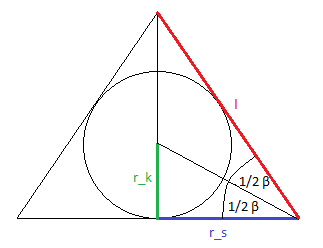

Rys. Przekrój stożka z wpisaną kulą - rysunek pomocniczy do wyznaczenia wzoru na promień kuli.


$$r_{k} = r_s \cdot tg\left(\frac{1}{2} \cdot arccos\left(\frac{r_s}{l}\right)\right)$$


Ponieważ szukamy maksimum objętość kuli, optymalizację będziemy przeprowadzać dla $F = \left\{ V_k(r_k(r_s, l)), \frac{1}{P_s(r_s, l)} \right\}$.

clear;
% Objętość kuli
V_k = @(r) (4/3) * pi * r^3;
% Pole stożka
P_s = @(r, l) pi * r * (r + l);

% Funkcja celu
% x(1) - promień stożka (r_s), x(2) - tworząca stożka (l)
% r_kuli = r_s * tg(0.5 * arccos(r_s / l))
fun = @(x) [1 / V_k( x(1) * tan(0.5 * acos(x(1) / x(2)))), P_s(x(1), x(2))];
% warunki początkowe
rs0 = 1;
x0 = [rs0, 2 * rs0];

% miminalne i maksymalne dopuszczalne wartości wymiarów stożka
lb = [0.01, 0.01];
ub = [100, 100];
%options = optimoptions('fminimax','Display','iter');
% Poszukiwanie minimum
x = fminimax(fun,x0,[],[],[],[],lb,ub, [], [])


Local minimum possible. Constraints satisfied.

fminimax stopped because the predicted change in the objective function
is less than the value of the function tolerance and constraints 
are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.5572    1.6718


%Sprawdzenie
V_kuli = V_k(x(1))

V_kuli = 0.7248

P_stozka = P_s(x(1), x(2))

P_stozka = 3.9022

### Funkcja fgoalattain

Funkcja `fgoalattain` w Matlab Optimization Toolbox służy do rozwiązywania problemów optymalizacji wielokryterialnej. Głównym celem tej funkcji jest minimalizacja odległości pomiędzy osiąganym wynikiem a zadanych celów dla wielu funkcji celu. W praktyce, `fgoalattain` pomaga znaleźć zestaw wartości zmiennych decyzyjnych, który spełnia określone cele dla każdej z funkcji celu jednocześnie.

Użytkownik może zdefiniować cele (target values), czyli oczekiwane wartości dla każdej funkcji celu. `fgoalattain` stara się znaleźć rozwiązanie, które jednocześnie minimalizuje odległość pomiędzy osiągniętymi wynikami a zadanymi celami dla wszystkich funkcji celu.

Funkcję stosuje się podobnie do `fminimax`, jednak mamy możliwość podania dwóch nowych parametrów (3 i 4 argument pozycyjny). Są to:

- *goal* - docelowe wartości zmiennych x;

- *weight* - wektor wag dla celów.

Argumenty wyjściowe również są takie same co w przypadku funkcji `fminimax`, za wyjątkiem trzeciego z nich. Wartość *maxfval*, zastępuje *attainfactor, *czyli współczynnik osiągnięcia celów. Jeśli jest on ujemny, cele zostały przekroczone, jeśli dodatni, cele nie zostały w pełni osiągnięte.

W celu zaprezentowania działania funkcji, można posłużyć się przykładem z dokumentacji.

Poszukujemy argumentu x dla funkcji F(x), dla którego jej wartość wynosi [3, 6], z równymi wagami dla każdej z funkcji składowych ([1, 1]).

fun = @(x)[2+(x-3)^2; 5+x^2/4];
goal = [3,6];
weight = [1,1];
x0 = 1;
x = fgoalattain(fun,x0,goal,weight)


Local minimum possible. Constraints satisfied.

fgoalattain stopped because the size of the current search direction is less than
twice the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x = 2.0000

fun(x)

ans =     3.0000
    6.0000


Jak widać, zostały osiągnięte dokładne docelowe wartości.

#### Przykład 10.1 z konspektu

Przykład prezentuje możliwość zastosowania funkcji fgoalattain.

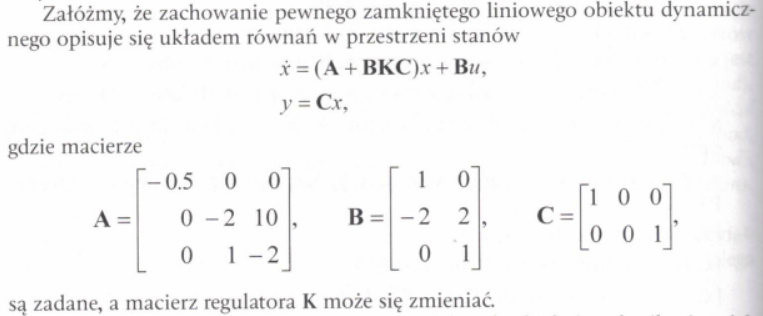

Zadanie polega na znalezieniu takiej macierzy regulatora $K$, o elementach z zakresu $[-4; 4]$, dla którego wartość wektora zmeinnych stanu $x$, to $[-5, -3, -1]$.

% Przykład 10.1 z konspektu optymalizacji wielokryterialnej
clear;

% Dane wartości macierzy
A = [-0.5 0 0; 0 -2 10; 0 1 -2];
B = [1 0; -2 2; 0 1];
C = [1 0 0; 0 0 1];
% warunki początkowe
K0 = [-1 -1; -1 -1];
% wektor celu
goal = [-5, -3, -1];
% wektor współczynników wagowych
weight = abs(goal);
% dolne i górne ograniczenia dla macierzy K
lb = -4 * ones(size(K0));
ub = 4 * ones(size(K0));

options = optimset('Display', 'iter');
[K, fval, attainfactor] = fgoalattain(@cw10_1, K0, goal, weight, [], [], [], [], lb, ub, [], options, A, B, C)


                 Attainment        Max     Line search     Directional 
 Iter F-count        factor    constraint   steplength      derivative   Procedure 
    0      6              0       1.88521                                            
    1     13          1.031       0.02998            1           0.745     
    2     20         0.3525       0.06863            1          -0.613     
    3     27        -0.1706        0.1071            1          -0.223    Hessian modified  
    4     34        -0.2236       0.06654            1          -0.234    Hessian modified twice  
    5     41        -0.3568      0.007894            1         -0.0812     
    6     48        -0.3645      0.000145            1          -0.164    Hessian modified  
    7     55        -0.3645             0            1        -0.00515    Hessian modified  
    8     62        -0.3675     0.0001549            1        -0.00812    Hessian modified twice  
    9     69        -0.3889      0.008327           

K =    -4.0000   -0.2564
   -4.0000   -4.0000


fval =    -6.9313
   -4.1588
   -1.4099


attainfactor = -0.3863

Cele nie zostały jednak osiągnięte dokładnie - współczynnik osiągnięcia celów (attainfactor), jest stosunkowo duży, a wartości funkcji w uzyskanym punkcie, znacznie różnią się od docelowych.

Aby to skorygować, możemy wprowadzić opcję dokładniego osiągnięcia wszystkich celów, korzystając z parametru *options*.

options = optimset('GoalsExactAchieve', 3);
[K, fval, attainfactor, ~, output] = fgoalattain(@cw10_1, K0, goal, weight, [], [], [], [], lb, ub, [], options, A, B, C)


Local minimum possible. Constraints satisfied.

fgoalattain stopped because the size of the current search direction is less than
twice the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


K =    -1.5953    1.2040
   -0.4201   -2.9047


fval =    -5.0000
   -3.0000
   -1.0000


attainfactor = 2.7375e-21

output = struct with fields:
         iterations: 8
          funcCount: 55
       lssteplength: 1
           stepsize: 8.9442e-11
          algorithm: 'active-set'
      firstorderopt: []
    constrviolation: 4.5114e-11
            message: '↵Local minimum possible. Constraints satisfied.↵↵fgoalattain stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 8.773942e-11,↵is less than 2*options.StepTolerance = 1.000000e-06, and the maximum constraint ↵violation, 4.511413e-11, is less than options.ConstraintTolerance = 1.000000e-06.↵↵'


Jak widać, dzięki temu, cele zostały osiagnięte dokładnie, warto zauważyć również, że liczba iteracji spadła - z 11 do 8.

## Wnioski

Funkcja `fminimax` jest szczególnie przydatna w sytuacjach, gdzie istnieje konieczność minimalizacji ryzyka lub maksymalnych strat, jednocześnie uwzględniając różne aspekty lub cele. Przykłady zastosowań obejmują projektowanie systemów, planowanie zasobów czy decyzje inwestycyjne, gdzie równoczesne minimalizowanie maksymalnych kosztów lub ryzyka jest istotne. Dzięki tej funkcji, możliwe jest efektywne rozwiązywanie problemów optymalizacji zorientowanych na minimalizację maksymalnej wartości spośród wielu funkcji celu.

Prowadzący zajęcia, zwrócił uwagę na to, że mimo, że zadanie problemowe, związane z zastosowaniem funkcji `fminimax, `nie było matematycznie skomplikowane, to jednak sprawiło wielu osobom problem. Może być to związane z błędnym podaniem punktu początkowego dla metody `fminimax. `Należy pamiętać, że zmienne, składające się na wektor $x$, oznaczają długości promienia podstawy stożka oraz tworzącej tego stożka. Tworząca musi być dłuższa od promienia podstawy. W szczególności, nie może więc być mu równa. Kiedy podamy np. $x0 = [1, 1]$, lub $x0 = [0, 0]$, nie otrzymamy rozwiązania.

Funkcja `fgoalattain` jest użyteczna w sytuacjach, gdzie istnieje potrzeba jednoczesnego spełnienia wielu celów, a te cele mogą być zdefiniowane w kontekście różnych funkcji celu. Przykłady zastosowań obejmują projektowanie systemów, gdzie równocześnie należy uwzględniać różne aspekty i cele, takie jak koszty, wydajność czy bezpieczeństwo. Dzięki `fgoalattain`, możliwe jest efektywne znajdowanie rozwiązań, które balansują pomiędzy różnymi celami w problemach optymalizacji wielokryterialnej.

Jeżeli zależy nam na dokładnym osiągnięciu celów, warto posłużyć się odpowiednimi opcjami dla tej funkcji.

function F = cw10_1(K, A, B, C)
    F = sort(eig(A+B*K*C));
end